data = readtable("scan_1632596590.csv");

xPos = deg2rad(data.xPos);
yPos = deg2rad(data.yPos + 90);
distance = data.distance;

mask1 = abs(distance) < 30;
xPos_filtered = xPos(mask1);
yPos_filtered = yPos(mask1);
distance_filtered = distance(mask1);

[x, y, z] = sph2cart(xPos_filtered, yPos_filtered, distance_filtered);
mask = (abs(x) < 100) & (abs(y) < 100) & (abs(z) < 100);

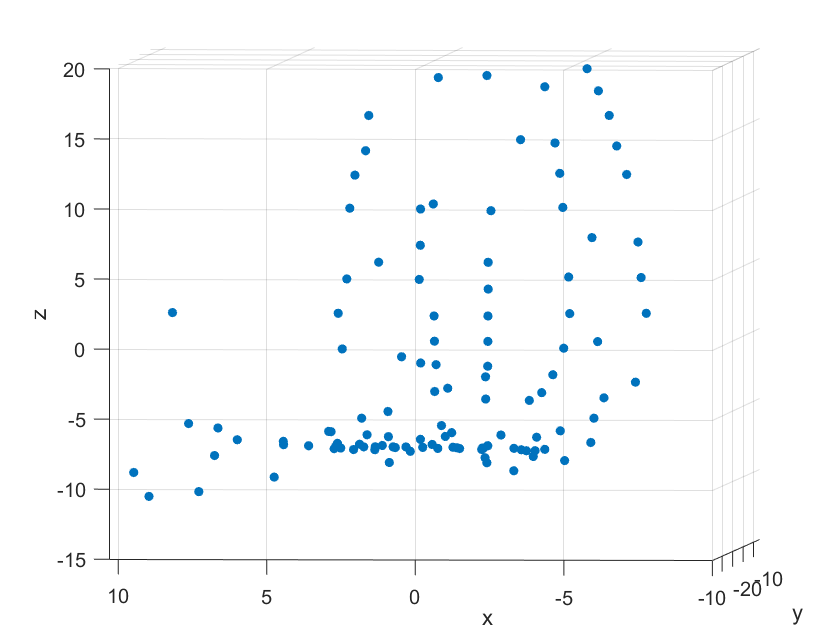

scatter3(x(mask), y(mask), z(mask), 250, ".")
xlabel("x"); ylabel("y"); zlabel("z");